close all
clc
clear

syms x y t % variables
syms theta1(t) theta2(t) gamma1(t) gamma2(t) delta_theta1(t) delta_theta2(t) delta_gamma1(t) delta_gamma2(t) % functions

% Parameters
xs = sym("x_s")

$$xs = x_{s}$$

xdelta = sym("x_delta")

$$xdelta = x_{\delta }$$

beta = sym("beta")

$$beta = \beta$$

e = sym("e")

$$e = e$$

delta = sym("delta")

$$delta = \delta$$

h = sym("h")

$$h = h$$

c = sym("c")

$$c = c$$

sig = sym("sigma")

$$sig = \sigma$$

K1 = sym("K1")

$$K1 = K_{1}$$

K2 = sym("K2")

$$K2 = K_{2}$$

K3 = sym("K3")

$$K3 = K_{3}$$

K4 = sym("K4")

$$K4 = K_{4}$$

s = sym("s")

$$s = s$$

Uinf = sym("U_inf")

$$Uinf = U_{\inf}$$

rhoinf = sym("rho_inf")

$$rhoinf = \rho_{\inf}$$


% Some numeric variables
rhoinfnum = 1.25;
uinfnum = 1;
betanum = 1;
enum = 1;
xdeltanum = 20e-2;
xsnum = 20e-2;
hnum = 80e-2;
cnum = 60e-2;
sigmanum = 5;
snum = 20e-2;
K1num = 6e3;
K2num = 6e3;
K3num = 1e3; 
K4num = 8e3;


% Kinetics
w1(x,y,t) = gamma1*y - theta1*(x-xs)

$$w1(x, y, t) = y\,\gamma_{1}\left(t\right)-\theta_{1}\left(t\right)\,\left(x-x_{s}\right)$$

w2(x,y,t) = gamma1*h + gamma2*(y-h) - theta2*(x-xs)

$$w2(x, y, t) = h\,\gamma_{1}\left(t\right)-\gamma_{2}\left(t\right)\,\left(h-y\right)-\theta_{2}\left(t\right)\,\left(x-x_{s}\right)$$


% Kinetic energy
T = int(int(sig/2*(diff(w1,t))^2,x,0,c),y,0,h) + int(int(sig/2*(diff(w2,t))^2,x,0,c),y,h,2*h)

$$T(t) = \begin{array}{l} h\,\left(\frac{\sigma \,c^{3}\,\sigma_{2}}{6}-\frac{\sigma \,c^{2}\,x_{s}\,\sigma_{2}}{2}+\frac{\sigma \,c\,{x_{s}}^{2}\,\sigma_{2}}{2}\right)-h^{2}\,\left(\frac{c^{2}\,\sigma \,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{4}-\frac{c\,\sigma \,x_{s}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{2}\right)+\frac{2\,c\,h^{3}\,\sigma \,{\left(\frac{\partial }{\partial t}\gamma_{1}\left(t\right)\right)}^{2}}{3}+\frac{c\,h^{3}\,\sigma \,{\left(\frac{\partial }{\partial t}\gamma_{2}\left(t\right)\right)}^{2}}{6}+\frac{c^{3}\,h\,\sigma \,\sigma_{1}}{6}+\frac{c\,h^{3}\,\sigma \,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{2}+\frac{c\,h\,\sigma \,{x_{s}}^{2}\,\sigma_{1}}{2}-\frac{c^{2}\,h\,\sigma \,x_{s}\,\sigma_{1}}{2}-\frac{c^{2}\,h^{2}\,\sigma \,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{2}-\frac{c^{2}\,h^{2}\,\sigma \,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)}{4}+c\,h^{2}\,\sigma \,x_{s}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)+\frac{c\,h^{2}\,\sigma \,x_{s}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$

 
% Potential energy
U = K1/2*(w1(0,0,t))^2 + ...
    K2/2*(w2(0,h,t) - w1(0,h,t))^2 + ...
    K3/2*(w2(xs,2*h,t))^2 + ...
    K4/2*(gamma1(t)*s - gamma2(t)*s)^2   

$$U = \frac{K_{3}\,{\left(h\,\gamma_{1}\left(t\right)+h\,\gamma_{2}\left(t\right)\right)}^{2}}{2}+\frac{K_{4}\,{\left(s\,\gamma_{1}\left(t\right)-s\,\gamma_{2}\left(t\right)\right)}^{2}}{2}+\frac{K_{2}\,{\left(x_{s}\,\theta_{1}\left(t\right)-x_{s}\,\theta_{2}\left(t\right)\right)}^{2}}{2}+\frac{K_{1}\,{x_{s}}^{2}\,{\theta_{1}\left(t\right)}^{2}}{2}$$


q = {theta1(t) gamma1(t) theta2(t) gamma2(t)}

q = 1×4 cell array
    {[theta1(t)]}    {[gamma1(t)]}    {[theta2(t)]}    {[gamma2(t)]}



% a) Find M and K, and compute the natural modes and frequencies

for i=1:4
    for j=1:4
        M(i,j) = simplify(diff(diff(diff(T,diff(q{i},t)),t),diff(diff(q{j},t),t)));
    end
end
M

$$M = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & 0 & 0\\ \sigma_{1} & \frac{4\,c\,h^{3}\,\sigma }{3} & -\frac{c\,h^{2}\,\sigma \,\left(c-2\,x_{s}\right)}{2} & \frac{c\,h^{3}\,\sigma }{2}\\ 0 & -\frac{c\,h^{2}\,\sigma \,\left(c-2\,x_{s}\right)}{2} & \sigma_{2} & \sigma_{1}\\ 0 & \frac{c\,h^{3}\,\sigma }{2} & \sigma_{1} & \frac{c\,h^{3}\,\sigma }{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{c\,h^{2}\,\sigma \,\left(c-2\,x_{s}\right)}{4}\\ \sigma_{2}=\frac{c\,h\,\sigma \,\left(c^{2}-3\,c\,x_{s}+3\,{x_{s}}^{2}\right)}{3} \end{array}$$


for i=1:4
    for j=1:4
        K(i,j) = simplify(diff(diff(U, q{i}), q{j}));
    end
end
K

$$K = \begin{array}{l} \left(\begin{array}{cccc} {x_{s}}^{2}\,\left(K_{1}+K_{2}\right) & 0 & -K_{2}\,{x_{s}}^{2} & 0\\ 0 & \sigma_{2} & 0 & \sigma_{1}\\ -K_{2}\,{x_{s}}^{2} & 0 & K_{2}\,{x_{s}}^{2} & 0\\ 0 & \sigma_{1} & 0 & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=K_{3}\,h^{2}-K_{4}\,s^{2}\\ \sigma_{2}=K_{3}\,h^{2}+K_{4}\,s^{2} \end{array}$$


Mnum = double(subs(M,[xs,h,c,sig],[xsnum,hnum,cnum,sigmanum]))

Mnum =     0.0960   -0.0960         0         0
   -0.0960    2.0480   -0.1920    0.7680
         0   -0.1920    0.0960   -0.0960
         0    0.7680   -0.0960    0.5120


Knum = double(subs(K,[xs,h,s,K1,K2,K3,K4],[xsnum,hnum,snum,K1num,K2num,K3num,K4num]))

Knum =    480     0  -240     0
     0   960     0   320
  -240     0   240     0
     0   320     0   960



[Q,W2] = eig(Knum,Mnum);
Q

Q =     0.4822    1.9035   -0.7739   -2.6944
   -0.5670    0.5365    0.7208   -0.4112
    0.7964    3.0127    0.5318    1.8218
   -0.0312    0.0310   -1.8482    1.2142



wn = sqrt(diag(W2))/2/pi

wn =     3.1847
    6.0662
    9.3865
   14.1419



% b) Steady aeroelasticity

deltaW = pi*rhoinf*Uinf^2*c*(int(y*theta1*delta_gamma1,y,0,h) + ...
    int((xs-c/4)*theta1*delta_theta1,y,0,h) + ...
    int(h*theta2*delta_gamma1,y,h,2*h) + ...
    int((y-h)*theta2*delta_gamma2,y,h,2*h) + ...
    int((xs-c/4)*theta2*delta_theta2,y,h,2*h) + ...
    int((3*beta/(2*beta+1))*h*delta*delta_gamma1,y,h*(2-e),2*h) + ...
    int((3*beta/(2*beta+1))*(y-h)*delta*delta_gamma2,y,h*(2-e),2*h) + ...
    int((3*beta/(2*beta+1))*(xs - xdelta)*delta*delta_theta2,y,h*(2-e),2*h))

$$deltaW(t) = \pi \,{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\left(\frac{h^{2}\,\delta_{\mathrm{gamma1}}\left(t\right)\,\theta_{1}\left(t\right)}{2}+h^{2}\,\delta_{\mathrm{gamma1}}\left(t\right)\,\theta_{2}\left(t\right)+\frac{h^{2}\,\delta_{\mathrm{gamma2}}\left(t\right)\,\theta_{2}\left(t\right)}{2}-\frac{h\,\delta_{\mathrm{theta1}}\left(t\right)\,\theta_{1}\left(t\right)\,\left(c-4\,x_{s}\right)}{4}-\frac{h\,\delta_{\mathrm{theta2}}\left(t\right)\,\theta_{2}\left(t\right)\,\left(c-4\,x_{s}\right)}{4}+\frac{3\,\beta \,\delta \,e\,h^{2}\,\delta_{\mathrm{gamma1}}\left(t\right)}{2\,\beta +1}-\frac{3\,\beta \,\delta \,e\,h^{2}\,\delta_{\mathrm{gamma2}}\left(t\right)\,\left(e-2\right)}{2\,\left(2\,\beta +1\right)}-\frac{3\,\beta \,\delta \,e\,h\,\delta_{\mathrm{theta2}}\left(t\right)\,\left(x_{\delta }-x_{s}\right)}{2\,\beta +1}\right)$$


q2 = {delta_theta1(t) delta_gamma1(t) delta_theta2(t) delta_gamma2(t)}

q2 = 1×4 cell array
    {[delta_theta1(t)]}    {[delta_gamma1(t)]}    {[delta_theta2(t)]}    {[delta_gamma2(t)]}



for i=1:4
    for j=1:4
        A(i,j) = simplify(diff(diff(deltaW, q2{i}), q{j}));
    end
end
A

$$A = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & 0 & 0 & 0\\ \frac{\pi \,{U_{\inf}}^{2}\,c\,h^{2}\,\rho_{\inf}}{2} & 0 & \pi \,{U_{\inf}}^{2}\,c\,h^{2}\,\rho_{\inf} & 0\\ 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & \frac{\pi \,{U_{\inf}}^{2}\,c\,h^{2}\,\rho_{\inf}}{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\pi \,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,\left(c-4\,x_{s}\right)}{4} \end{array}$$

Anum = double(subs(A,[Uinf,rhoinf,xs,c,h],[uinfnum,rhoinfnum,xsnum,cnum,hnum]))

Anum =     0.0942         0         0         0
    0.7540         0    1.5080         0
         0         0    0.0942         0
         0         0    0.7540         0



for i=1:4
    Fdelta(i,1) = simplify(diff(diff(deltaW, q2{i}), delta));
end
Fdelta = Fdelta(:,1)

$$Fdelta = \left(\begin{array}{c} 0\\ \frac{3\,\pi \,{U_{\inf}}^{2}\,\beta \,c\,e\,h^{2}\,\rho_{\inf}}{2\,\beta +1}\\ -\frac{3\,\pi \,{U_{\inf}}^{2}\,\beta \,c\,e\,h\,\rho_{\inf}\,\left(x_{\delta }-x_{s}\right)}{2\,\beta +1}\\ -\frac{3\,\pi \,{U_{\inf}}^{2}\,\beta \,c\,e\,h^{2}\,\rho_{\inf}\,\left(e-2\right)}{2\,\left(2\,\beta +1\right)} \end{array}\right)$$

Fdeltanum = double(subs(Fdelta,[Uinf,rhoinf,beta,c,e,h,xs,xdelta],[uinfnum,rhoinfnum,betanum,cnum,enum,hnum,xsnum,xdeltanum]))

Fdeltanum =          0
    1.5080
         0
    0.7540



% b1) Divergence speed
[v,d] = eig(Knum,Anum);
Ud = sqrt(diag(d));
for q = 1:1:size(d,1)
    if Ud(q) < 0 % elimination of negative values
        Ud(q) = 0;
    elseif isreal(Ud(q)) == 0 % elimination of complex values
        Ud(q) = 0;
    elseif Ud(q) > 10^10 % elimination of infinite values
        Ud(q) = 0;
    end
end
if min(Ud(Ud>0)) ~= 0
    Ud = min(Ud(Ud>0));
else
    Ud = 0;
end
Ud

Ud = 31.1876


% b2) Control reversal speed
% N = 10;
N = 2;
for ii=2:1:N
    for jj=2:1:N

        beta_num(ii,jj) = 0.5/(N-1)*(ii-1);
        e_num(ii,jj) = 1/(N-1)*(jj-1);
        x_delta_num = (60e-2)*(2-beta_num(ii,jj))/4;

        ratio_L = 1 + (2*beta+1)/(3*beta)*[1 0 1 0]*pi*rhoinf*Uinf^2*c*h*inv(K-A)*Fdelta/(pi*rhoinf*Uinf^2*c*h)
        
        for i=1:1:200
            ratio_L_num(i) = double(subs(ratio_L,[beta,e,xdelta,K1,K2,xs,Uinf,c,h,rhoinf],[beta_num(ii,jj),e_num(ii,jj),x_delta_num,K1num,K2num,xsnum,i,cnum,hnum,rhoinfnum]));
            Uinfty(i) = i;
        end
        
            % Compute Ur
            find_Ur = false;
            kk = 1;
            while find_Ur == false
                if (ratio_L_num(kk) < 0)
                    pos_Ur = kk;
                    find_Ur = true;
                else
                kk = kk + 1;
                end
            end
            Ur1 = double(Uinfty(kk-1));
            Ur2 = double(Uinfty(kk));
            l_ratio1 = ratio_L_num(kk-1);
            l_ratio2 = ratio_L_num(kk);
            Ur(ii-1,jj-1) = Ur1 - l_ratio1*(Ur2 - Ur1)/(l_ratio2 - l_ratio1) % Interpolate
        
        %plot(Uinfty,ratio_L_num)
    end
end

$$ratio\_L = \begin{array}{l} 1-\frac{3\,\beta \,e\,\left(\frac{4\,\pi \,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,\left(2\,\beta +1\right)\,\left(4\,K_{1}\,{x_{s}}^{2}+4\,K_{2}\,{x_{s}}^{2}+\pi \,{U_{\inf}}^{2}\,c^{2}\,h\,\rho_{\inf}-4\,\pi \,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,x_{s}\right)}{\sigma_{1}}+\frac{16\,\pi \,K_{2}\,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,{x_{s}}^{2}\,\left(2\,\beta +1\right)}{\sigma_{1}}\right)\,\left(x_{\delta }-x_{s}\right)}{2\,\beta +1}\\ \mathrm{where}\\ \sigma_{1}=3\,\beta \,\left(16\,K_{1}\,K_{2}\,{x_{s}}^{4}+{U_{\inf}}^{4}\,c^{4}\,h^{2}\,{\rho_{\inf}}^{2}\,\pi^{2}-8\,{U_{\inf}}^{4}\,c^{3}\,h^{2}\,{\rho_{\inf}}^{2}\,x_{s}\,\pi^{2}+16\,{U_{\inf}}^{4}\,c^{2}\,h^{2}\,{\rho_{\inf}}^{2}\,{x_{s}}^{2}\,\pi^{2}+4\,\pi \,K_{1}\,{U_{\inf}}^{2}\,c^{2}\,h\,\rho_{\inf}\,{x_{s}}^{2}+8\,\pi \,K_{2}\,{U_{\inf}}^{2}\,c^{2}\,h\,\rho_{\inf}\,{x_{s}}^{2}-16\,\pi \,K_{1}\,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,{x_{s}}^{3}-32\,\pi \,K_{2}\,{U_{\inf}}^{2}\,c\,h\,\rho_{\inf}\,{x_{s}}^{3}\right) \end{array}$$

Ur = 24.7839


% contour(beta_num(2:10,2:10),e_num(2:10,2:10),Ur)
% colorbar

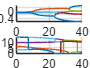


% c) Flutter speed considering Theodorsen's aerodynamics

% A0 matrix
A0 = A/(pi*rhoinf*Uinf^2*c*h);

% Circulatory terms matrix
A1c = [(xs-3*c/4)*(xs-c/4)/(2*c),  (h*(xs-c/4))/(4*c), 0,                             0
         h*(xs-3*c/4)/(4*c),       (2*h^2)/(3*c),      (h*(xs-3*c/4))/(2*c),          h^2/(4*c)
         0,                        h*(xs-c/4)/(2*c),   (xs-c/4)*(xs-3*c/4)/(2*c),     h*(xs-c/4)/(4*c)
         0,                        h^2/(4*c),          h*(xs-3*c/4)/(4*c),            h^2/(6*c)];

% Non-circulatory terms matrix
A1nc = [(xs-3*c/4)/2, 0, 0,            0
         h/4,         0, h/2,          0
         0,           0, (xs-3*c/4)/2, 0
         0,           0, h/4,          0];

% Some numeric matrices
A1cnum = double(subs(A1c,[xs,c,h],[xsnum,cnum,hnum]));
A1ncnum = double(subs(A1nc,[xs,c,h],[xsnum,cnum,hnum]));
A0num = double(subs(A0,[xs,c,h],[xsnum,cnum,hnum]));


% c1) p method (algorithm from slide T2.2-5)

U_ = linspace(0.001,40,501); % Velocities vector
for i = 1:length(U_)
    
    % Compute the effective matrices
    Ceffnum = ((pi*rhoinfnum*U_(i)*cnum^2*hnum)/2)*(A1cnum-A1ncnum);
    Keffnum = Knum - pi*rhoinfnum*U_(i)^2*cnum*hnum*A0num;
    
    % Extend the system
    Anum = [Keffnum, zeros(4,4); zeros(4,4), eye(4,4)];
    Bnum = [-Ceffnum, -Mnum; eye(4,4), zeros(4,4)];

    [Vp,Dp] = eig(Anum,Bnum); % If we don't solve them in any specific way, the plots of the flutter will have some jumps.
    
    % we can sort the values so that to avoid those jumps
    p = diag(Dp);
    [~,indsorted] = sort(real(p),'descend');
    p = p(indsorted);
    Vp = Vp(:,indsorted);
    Vp_(:,:,i) = Vp;
    p_(:,i) = p;
%     if max(real(p_(:,i))) > 1e-8
%         % stop the simulation (to avoid taking as a solution one of the jumps)
%     end
end
figure
for j = 1:8
    subplot(2,1,1)
    hold on
    plot(U_,real(p_(j,:).*cnum./(2*U_)));
    xlabel('U')
    ylabel('p_R c / 2U\infty')
    grid on
    subplot(2,1,2)
    hold on
    plot(U_,abs(imag(p_(j,:))/(2*pi)));
    xlabel('U')
    ylabel('p_I / 2\pi [Hz]')
    grid on
end

%NOTA: la Uflutter ha d'estar entre 9.8 i 9.9 aprox!

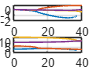


% c2) k method (algorithm from slide T2.2-9)
% This method imposes a loop for different values of k
% We need to define the Theodorsen's function:
C = @(k) 1 - 0.165/(1-1i*0.045/k) - 0.335/(1-1i*0.3/k);

% Definition of the inverse k vector (k^-1 = (2*Uinf)/(omega*c))
invk_ = linspace(0.001,10,500);
l_ = zeros(4,length(invk_));
Vk_ = zeros(4,4,length(invk_));

% Sweep through inverse of k
for i = 1:length(invk_)
    % Get reduced frequency
    k = 1/invk_(i);
    % Compute effective mass expression
    Meffnum = Mnum + pi*rhoinfnum*cnum^3*hnum/(4*k^2)*(C(k)*A0num - 1i*k*(C(k)*A1cnum - A1ncnum));
    
    % Solve the eigenvalues problem
    [Vk,Dk] = eig(Meffnum,Knum); % We use the opposite (usually it is eigs(K,M) but now it the opposite: see equations of page T2.2-8 --> we have the eigenvalue (lambda) multiplying the K matrix instead of the Meff matrix)
    % Sort (the following algorithm analyses the previous iteration and saves the colsest one to the actual iteration, and we will elimiate this value)
    if i > 1
        % it could be added to the p-method to elimiate the jupms
        l = diag(Dk);
        tosort = 1:4;
        for j = 1:4
            [~,jmin] = min(abs(real(l(tosort))-real(l_(j,i-1))) + abs(imag(l(tosort))-imag(l_(j,i-1)))); % to find from all the previous eigenvalues which is the closest one (difference between the real part and the imaginary part)
            l_(j,i) = l(tosort(jmin));
            Vk_(:,j,i) = Vk(:,tosort(jmin));
            tosort(jmin) = [];
        end
    else
        l_(:,1) = diag(Dk);
    end
end
wk_ = sqrt(1./real(l_));
gk_ = imag(l_)./real(l_);
Uk_ = wk_*cnum.*invk_/2;


figure
subplot(2,1,1)
plot(Uk_',gk_');
xlabel("U_\infty");
ylabel("g");
xlim([0 40])
grid on
subplot(2,1,2)
plot(Uk_',wk_'/(2*pi));
xlabel("U_\infty ");
ylabel("\omega / 2\pi [Hz]");
xlim([0 40])
grid on


% NOTE: solution is around 14 m/s --> with the p-method was 9.8 m/s aprox

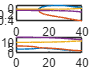


% c3) p-k method (algorithm from slide T2.2-12)
tol = 1e-6; % Convergence tolerance
max_iter = 100;


% Variables
gam_ = zeros(4, length(U_));
w_ = zeros(4, length(U_));
Vpk_= zeros(4, length(U_));

% First guess for frequencies
[~,Ds] = eig(Knum,Mnum);
w_(:,1) = sqrt(diag(Ds));

% Loop through velocites
for i = 1:length(U_)

    if i>1
        w_(:,i) = w_(:,i-1);
        gam_(:,i) = gam_(:,i-1);
    end
    
    for j = 1:4
        conv = 1;
        iter = 0;
        
        while conv > tol && iter < max_iter
            iter = iter+1;
            
            % Get reduced frequency
            k = w_(j,i)*cnum/(2*U_(i));
            
            % Compute effective matrices
            Keff = Knum - pi*rhoinfnum*U_(i)^2*cnum*hnum*(C(k)*A0num - 1i*k*(C(k)*A1cnum-A1ncnum));
            
            % Extend system matrices
            Anum = [Keff, zeros(4,4); zeros(4,4), eye(4,4)];
            Bnum = [zeros(4), -Mnum; eye(4,4), zeros(4,4)];

            % Solve eigenvalues
            [Vpk, Dpk] = eig(Anum,Bnum);
            p = diag(Dpk);
            
            % Look for closest node to initial guess (w_ and gam_)
            [conv,jmin] = min(abs(real(p)-gam_(j,i)) + abs(imag(p)-w_(j,i)));
            
            % Store the newer values as initial guesses or previous values
            w_(j,i) = imag(p(jmin));
            gam_(j,i) = real(p(jmin));
            Vpk_(:,j,i) = Vpk(1:4,jmin);
            
            
        
        end
        
    end
    
end

figure
subplot(2,1,1)
plot(U_, gam_.*cnum./(2*U_))
xlabel("U_\infty")
ylabel("\gammac/2U\infty")
subplot(2,1,2)
plot(U_, w_/(2*pi))
xlabel("U_\infty")
ylabel("\omega/ 2\pi [Hz]")